img = imread("boston night.jpg");
% imshow(img)
pix11 = img(1,1); % give -> rows, col to get that pixel
doublePix11 = double(pix11);

whos pix11;

  Name       Size            Bytes  Class    Attributes

  pix11      1x1                 1  uint8              



whos doublePix11

  Name             Size            Bytes  Class     Attributes

  doublePix11      1x1                 8  double              



numel(img)*1

ans =     53747712


numel(img)*8

ans =    429981696


Color images have 3 values per pixel

colorImg = imread("yellowlily.jpg")

colorImg = 1632×1224×3 uint8 array
colorImg(:,:,1) =

    44    44    43    42    41    41    40    40    36    37    37    38    38    37    36    35    38    39    39    36    33    31    33    34    43    40    39    40    46    51    55    55    52    48    45    42    41    40    40    40    39    38    36    33    33    31    29    30    34    36    38    40    40    41    43    43    39    36    31    28    27    26    25    23    19    20    19    17    17    16    14    14    16    13    12    12    13    13    13     9     8     6     5     4     3     2     3     3     7     8     9    10     9     6     3     0     0     0    15    32    44    48    59    68    68    63    60    58    60    61    64    63    67    64    60    57    57    59    62    64    68    67    69    68    67    67    66    64    66    64    63    62    63    64    66    67    72    71    70    69    68    68    68    68    72    72    69    68    68    68    67    67    66    64    60    59    59    

Extracting the green intensity from the top left pixel. Channle numbers for

[red = 1, green = 2, blue = 3]

Syntax: `colorImg(row, col, <channel number>)`

colorImg(1,1,2)

ans = uint8
   104


Extracting all three color intensities by using colon. Syantx: `img(row, col, :)`

colorImg(1,1,:)

ans = 1×1×3 uint8 array
ans(:,:,1) =

   44


ans(:,:,2) =

   104


ans(:,:,3) =

   53


Extracting the green color pane from a color image display (2D-arry)

colorImg(:,:,2)

ans = 1632×1224 uint8 matrix
   104   104   103   102   101   101   100   100    96    97    97    98    98    97    96    95    96    97    97    94    91    89    89    90    96    93    92    93    97   102   106   108   105   103   100    97    94    93    93    93    90    89    87    84    81    79    75    74    71    69
   104   104   103   103   102   101   100   100    98    99    99    99    98    97    96    96    93    93    93    91    88    87    87    89    93    90    88    89    92    97   101   104   102   100    98    96    93    93    91    90    86    86    85    83    81    79    77    76    71    70
   104   104   103   103   102   101   101   101   101   101   101   101   100    98    97    96    92    94    93    91    89    88    89    91    90    86    83    82    85    91    95    99    97    96    96    94    93    90    89    87    83    83    83    82    80    80    78    77    72    70
   104   104   104   103   103   102   102   101   104   104   103  

 Visualizing green intensities as a grayscale image

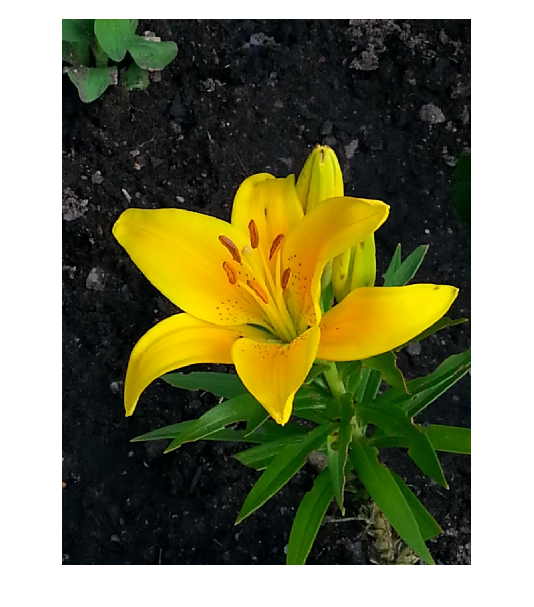

imshow(colorImg)

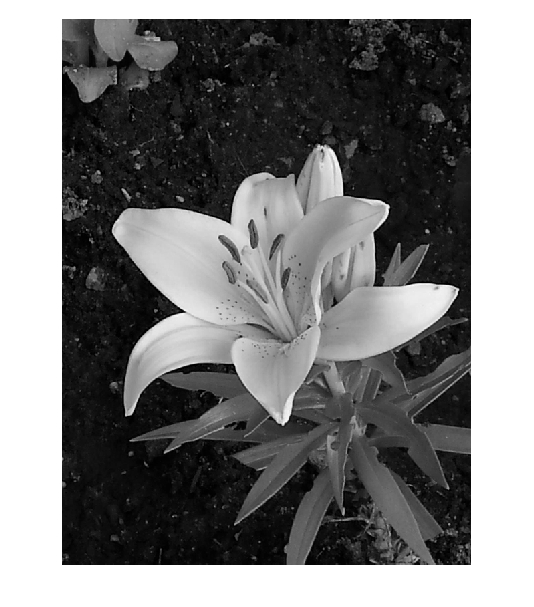

imshow(colorImg(:,:,2))

The yellow petals are being shows as high intensity value of green, means we cannot rely on only intensity value

Using the image tool (imtool)

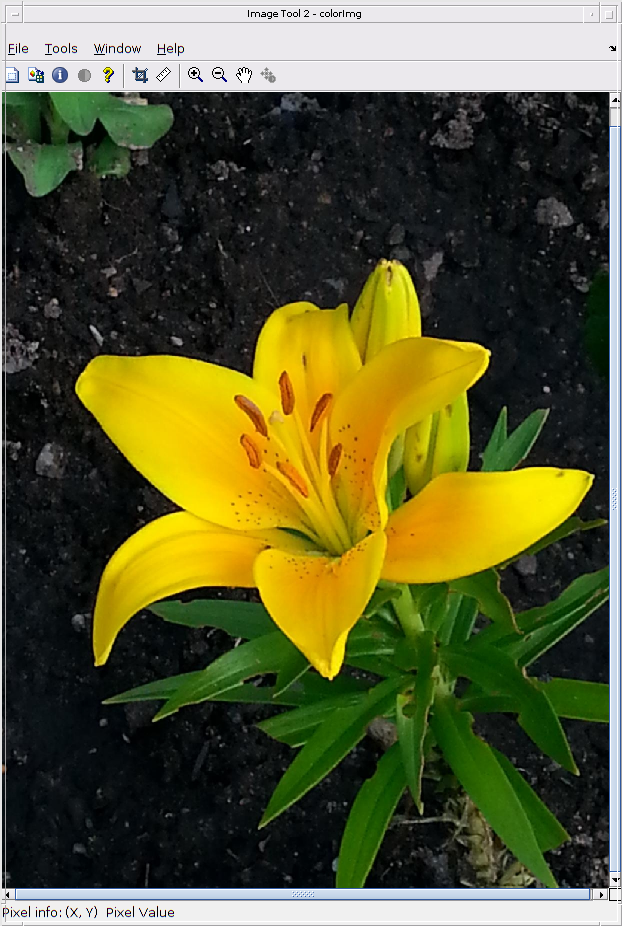

imtool(colorImg)

I cropped a specific area of the whole image using crop tool in imtool window, then exported that as a variable in the workspace. Now using it here

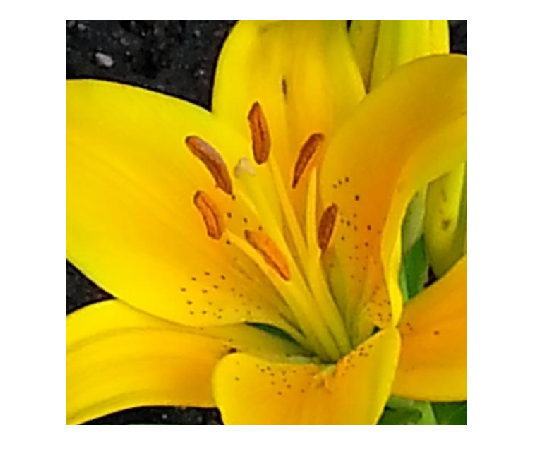

imshow(croppedImg)

### Learning Conclusions

- How to load and display images

- How grayscale and color images are represented in MATLAB as integer arrays

- How to extract image data from arrays by providing row, column and channel values or using the colon operator.

- How the Image Viewer App is used to interactively explore image data.